clear
path = '/Users/jorgeaugustomartinezortiz/Library/CloudStorage/OneDrive-BaylorUniversity/CASPER/projects/plasma_crystal/crystal_analysis/crystal_videos/laser_pulse_06102022.avi';
video = VideoReader(path)

video =   VideoReader with properties:

   General Properties:
            Name: 'laser_pulse_06102022.avi'
            Path: '/Users/jorgeaugustomartinezortiz/Library/CloudStorage/OneDrive-BaylorUniversity/CASPER/projects/plasma_crystal/crystal_analysis/crystal_videos'
        Duration: 1.163998836000000e+02
     CurrentTime: 0
       NumFrames: 3492

   Video Properties:
           Width: 1280
          Height: 1024
       FrameRate: 30.000030000030002
    BitsPerPixel: 8
     VideoFormat: 'Grayscale'


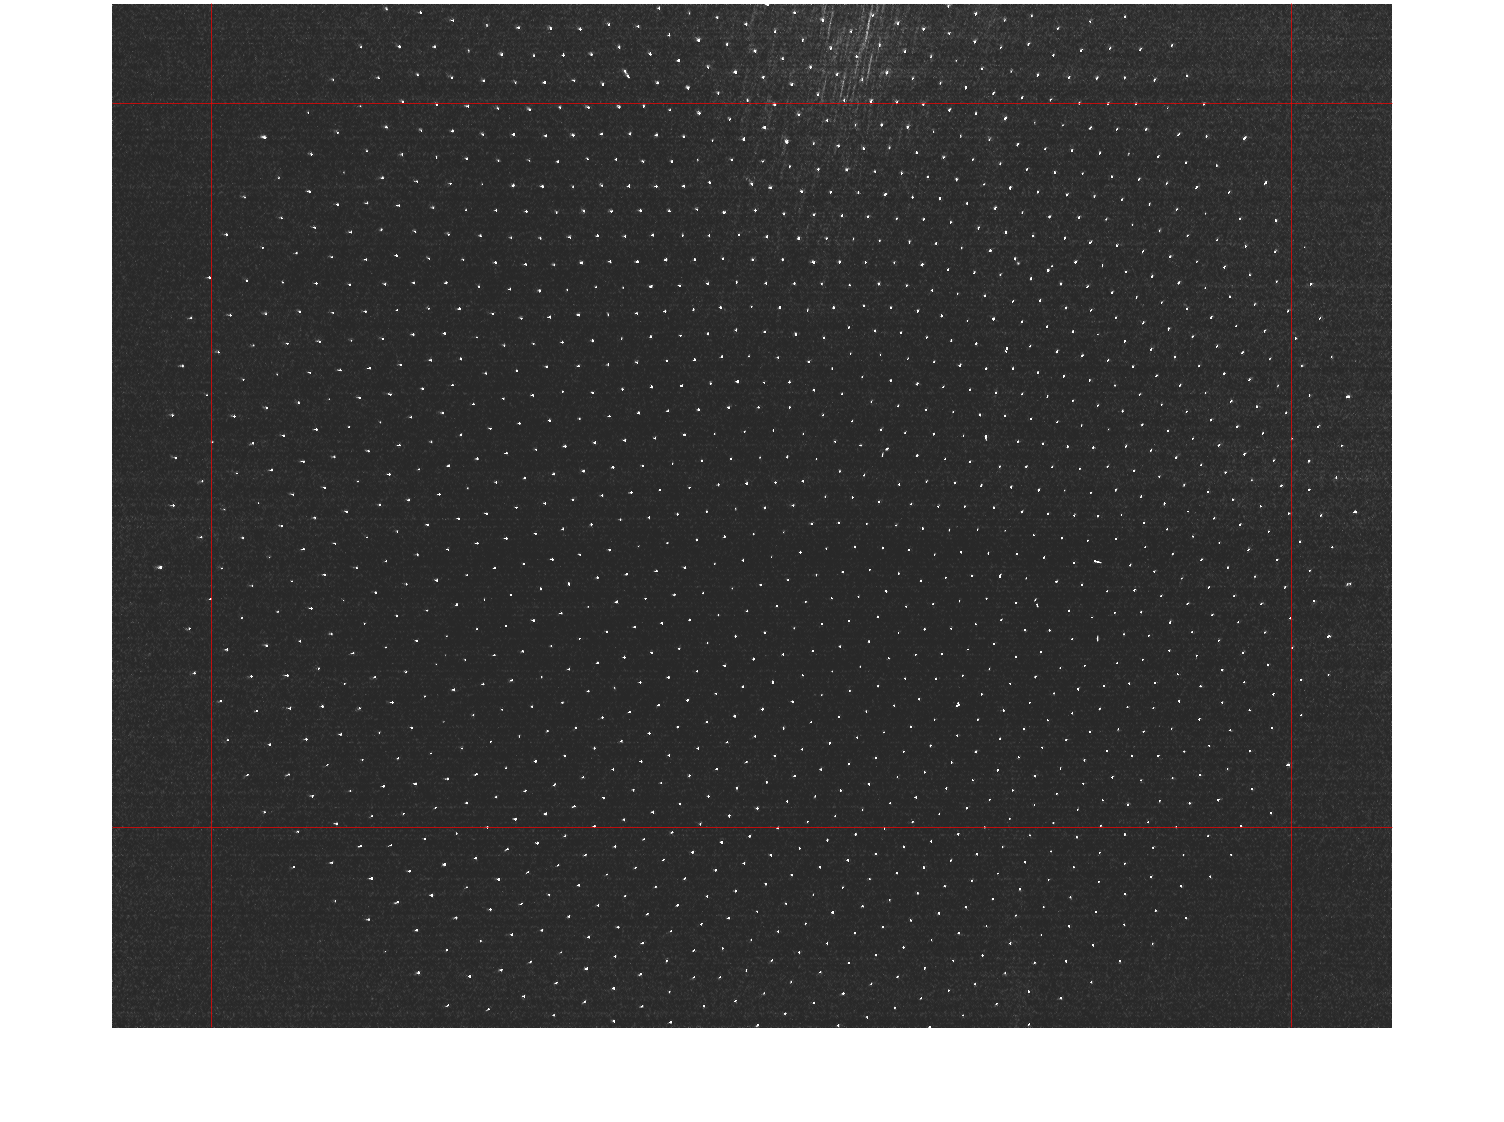

% PROCESS THE VIDEO
% Work here!!
leftCrop = 100;
rightCrop = 100;
lowerCrop = 200;
upperCrop = 100;

% Let this run
displayFrame(video,0,[leftCrop rightCrop],[upperCrop lowerCrop]);

function frame = getFrame(video,idx)
    if idx > video.NumFrames
        warning('Index outside valid range (0-%i). Reading last frame instead',video.NumFrames);
        idx = video.NumFrames-1;
    end

    video.CurrentTime = (1/video.FrameRate) * idx;
    frame = readFrame(video);
end

function img = displayFrame(video,idx,varargin)
    x_vec = [];
    y_vec = [];
    xcrop = false;
    ycrop = false;
    cropFormat = '-r';

    % INPUT VALIDATION
    if nargin > 2
        if nargin ~= 4
            error('Error: invalid number of input arguments')
        end

        x_vec = varargin{1};
        y_vec = varargin{2};

        % Validate x dimension
        if ~isempty(x_vec)
            if (x_vec(1) >= 1) && (x_vec(2) <= video.Width)
                xcrop = true;
            else 
                error('Invalid range in x dimension (0,%i)',video.Width)
            end
        end
    

        % Validate y dimension
        if ~isempty(y_vec) 
            if (y_vec(1) >= 1) && (y_vec(2) <= video.Width)
                ycrop = true;
            else
                error('Invalid crop in y dimension (0,%i)',video.Height)
            end
        end
    end

    img = imshow(getFrame(video,idx));
    if xcrop
        xline([x_vec(1) (video.Width-x_vec(2))],cropFormat)
    end

    if ycrop
        yline([y_vec(1) (video.Height-y_vec(2))],cropFormat)
    end
end

function playVideo(video,varargin)
    x_vec = varargin{1};
    y_vec = varargin{2};

    i = 0;
    img = displayFrame(video,0,x_vec,y_vec);
    while i < video.NumFrames
        img.CData = getFrame(video,i);
        drawnow
        pause(4/video.FrameRate);
        i = i+1;
    end
end

function stack = imgaussfiltStack(stack)
end
